% Prompt user for the number of polynomials
numPolynomials = input('Enter the number of polynomials: ');

% Initialize a cell array to hold polynomial coefficients
polynomials = cell(1, numPolynomials);

% Loop to get coefficients for each polynomial
for i = 1:numPolynomials
    coeffs = input(sprintf('Enter the coefficients for polynomial %d (e.g., [1 -3 2]): ', i));
    polynomials{i} = coeffs;
end

% Create a figure for plotting
figure;
hold on;

% Loop through each polynomial
for i = 1:length(polynomials)
    % Get the coefficients
    p = polynomials{i};

    % Calculate the roots
    r = roots(p);

    % Display the roots
    fprintf('Roots of polynomial %d: ', i);
    disp(r);

    % Define a function handle for the polynomial
    f = @(x) polyval(p, x);

    % Generate x values for plotting
    x = linspace(-3, 3, 400);

    % Plot the polynomial
    plot(x, f(x), 'DisplayName', sprintf('Polynomial %d', i));
end

Roots of polynomial 1: 

    -2
    -1



Roots of polynomial 2: 

   1.1573 + 1.3052i
   1.1573 - 1.3052i
  -1.3146 + 0.0000i



Roots of polynomial 3: 

   0.4516 + 1.1256i
   0.4516 - 1.1256i
  -1.2016 + 0.5057i
  -1.2016 - 0.5057i



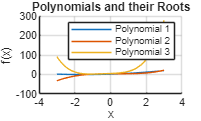


% Add labels and legend
xlabel('x');
ylabel('f(x)');
title('Polynomials and their Roots');
grid on;
legend show;
hold off;